# Activating and desactivating the optimization

[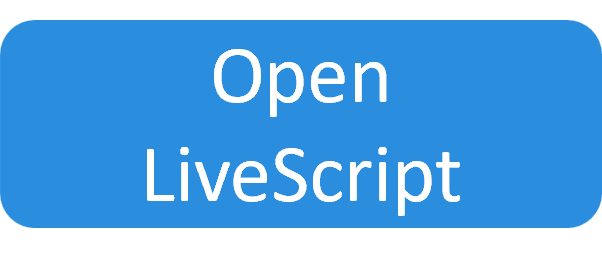](matlab:dxdzds.file='optimization_desactivation';dxdzds.outFile=fullfile(pwd,dxdzds.file); copyfile(which(['user_' dxdzds.file]),[dxdzds.outFile '.mlx']);open(dxdzds.outFile);clear dxdzds;)

### Desactivating and activating all the optimization at once

If needed, you can desactivate the optimization by calling `id.desactivateOptimizedDisplay()`. You can then reactivate all the optimization by calling `id.activateOptimizedDisplay()`.

*Example n°1:* desactivating the optimization for debugging purposes

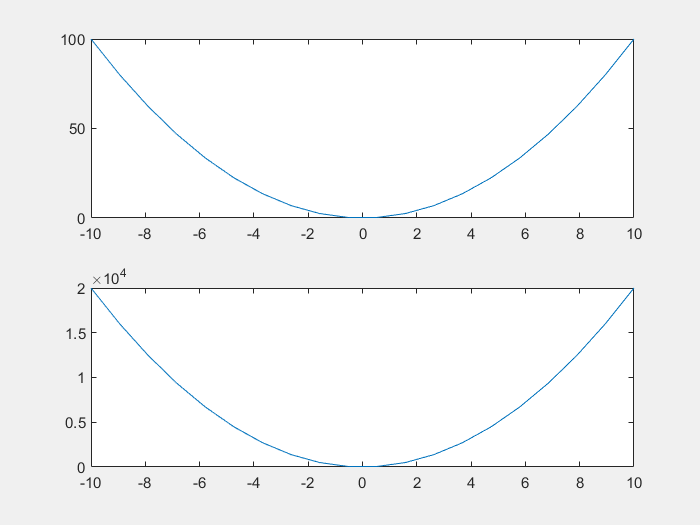

clearvars
close all
clc

id=iterativeDisplay;

id.desactivateOptimizedDisplay(); % This line desactivate all the optimizations


hFig=id.figure;
set(hFig,'visible','on'); % Undock the figure from the live editor
x=linspace(-10,10,20);y=x.^2;
for i=1:10
    if i<10
        id.newIteration;
    else
        id.finalIteration;
    end
    id.subplot(2,1,1);
    id.plot(x,y);
    id.subplot(2,1,2);
    id.plot(x,20*y*i);
    drawnow;
    pause(0.1);
end

### Desactivating the optimization for a single instruction

In the following example, we would like to change a figure title color based on some condition. The title optimization from the `iterativeDisplay` does not allows modifying the title `Color` property. So for this example, we may want to disable the optimization for the `title` method.

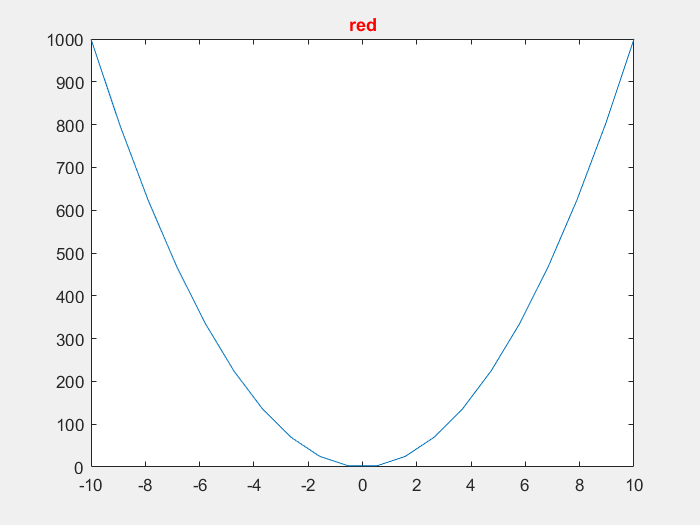

clearvars
close all
clc

id=iterativeDisplay;

% If the following line is commented, then the title color will not change,
% only the text will change
id.disableOptimization('title');

hFig=id.figure;
set(hFig,'visible','on'); % Undock the figure from the live editor

x=linspace(-10,10,20);y=x.^2;
for i=1:10
    if i<10
        id.newIteration;
    else
        id.finalIteration;
    end
    id.plot(x,y*i);
    if mod(i,2)==0
        id.title('red','Color','r');
    else
        id.title('green','Color','g');
    end
    drawnow;
    pause(0.1)
end